row_mem_one_read=[543,0, 0, 6, 1, 543, 1, 0, 484, 1];
row_boot_one_read=[76, 72, 30, 80, 71, 36, 0, 30, 0, 0];
row_boot_one_reg=[32, 62, 62, 58, 60, 0, 0, 0, 0, 30];
exit_50 =[row_boot_one_reg(1),row_boot_one_read(1), row_mem_one_read(1)];
exit_100 =[row_boot_one_reg(2),row_boot_one_read(2), row_mem_one_read(2)];
exit_150 =[row_boot_one_reg(3),row_boot_one_read(3), row_mem_one_read(3)];
exit_200 =[row_boot_one_reg(4),row_boot_one_read(4), row_mem_one_read(4)];
exit_250 =[row_boot_one_reg(5),row_boot_one_read(5), row_mem_one_read(5)];
exit_300 =[row_boot_one_reg(6),row_boot_one_read(6), row_mem_one_read(6)];
exit_350 =[row_boot_one_reg(7),row_boot_one_read(7), row_mem_one_read(7)];
exit_400 =[row_boot_one_reg(8),row_boot_one_read(8), row_mem_one_read(8)];
exit_450 =[row_boot_one_reg(9),row_boot_one_read(9), row_mem_one_read(9)];
exit_500 =[row_boot_one_reg(10),row_boot_one_read(10), row_mem_one_read(10)];


b0 = bar([exit_50;exit_100; exit_150; exit_200; exit_250;exit_300;exit_350;exit_400;exit_450;exit_500 ],'BarWidth', 0.8)

b0 =   1×3 Bar array:

    Bar    Bar    Bar


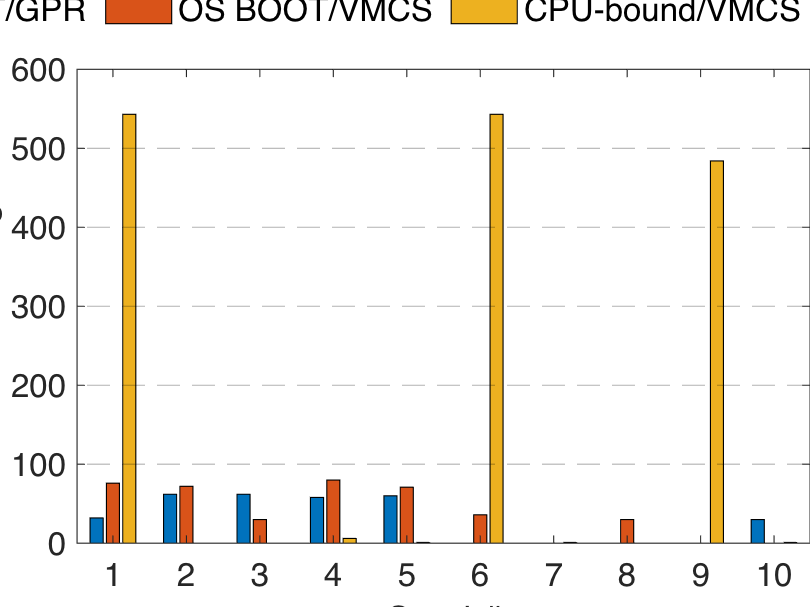

%set(b0, {'DisplayName'}, {'delay 00'}',{'delay 70'}',{'delay 80'}',{'delay 90'}');
set(gca, 'XTickLabel',{'1','2','3','4','5','6','7','8','9','10'})
set(b0, {'DisplayName'}, {'OS BOOT/GPR','OS BOOT/VMCS', 'CPU-bound/VMCS'}')
%ylim([0 1])
%title('After Clflush');
%xlabel('2048 KB memory fetching');
%ylabel('cpu cycles');
ax = gca; 
ax.FontSize = 15;
legend('Location', 'northoutside','FontSize',15);
legend('Orientation','horizontal');
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
set(gca, 'YGrid', 'on', 'XGrid', 'off')
ax.GridAlpha = 0.3;
ax.Layer = 'top';
xlabel("Seed #");
ylabel("Code coverage");
legend boxoff


%save figure
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
a2 = gcf;
a2.PaperPositionMode = 'auto';
fig_pos = a2.PaperPosition;
a2.PaperSize = [fig_pos(3) fig_pos(4)];
print(a2, strcat(fileparts(pwd),'/figures/fuzz_exp_CPU.pdf'),'-dpdf','-r0');